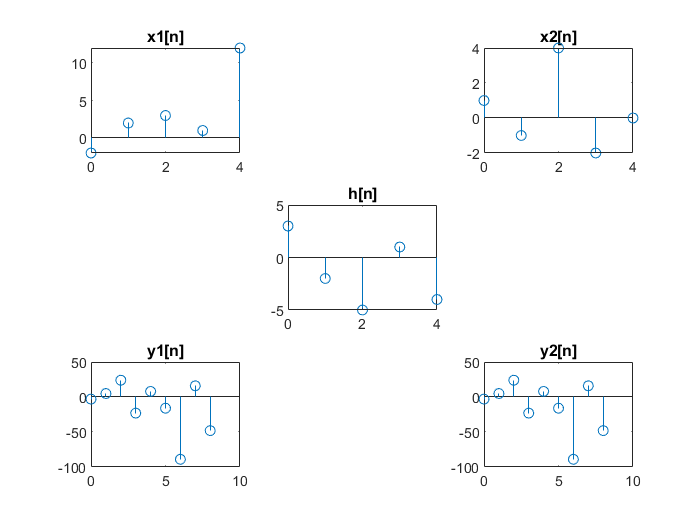

clc 
clear
close all

m=5;n=0:m-1;
x1=zeros(size(n));
x1(n==0)=-2;x1(n==1)=2;x1(n==2)=3;x1(n==3)=1;x1(n==4)=12;
subplot(3,3,1);stem(n,x1);title('x1[n]');
x2=zeros(size(n));
x2(n==0)=1;x2(n==1)=-1;x2(n==2)=4;x2(n==3)=-2;
subplot(3,3,3);stem(n,x2);title('x2[n]');
h=zeros(size(n));
h(n==0)=3;h(n==1)=-2;h(n==2)=-5;h(n==3)=1;h(n==4)=-4;
subplot(3,3,5);stem(n,h);title('h[n]');
z1=x1+x2;
y1=conv(z1,h);
p=0:2*m-2;
subplot(3,3,7);stem(p,y1);title('y1[n]');
z2=conv(x1,h);z3=conv(x2,h);y2=z2+z3;
subplot(3,3,9);stem(p,y2);title('y2[n]');